# 24 kHz to 4 kHz

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code generates a signal with two tones at 300 Hz and 3000 Hz. 

The tone at 3000 Hz will cause issues after downsampling because it's above the new Nyquist frequency.

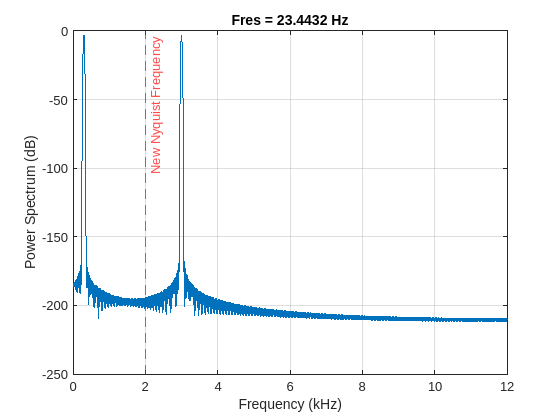

fs = 24000;
t = 0:1/fs:0.5;
sig = sin(2*pi*300*t) + sin(2*pi*3000*t);
pspectrum(sig, fs)
xline(2, "r--", "New Nyquist Frequency")

## Task 1

To downsample a signal so that there's no antialiasing filter, you can use the `downsample` function:

`y` `=` `downsample``(``x``,``n``)`

where `n` is an integer downsampling factor.

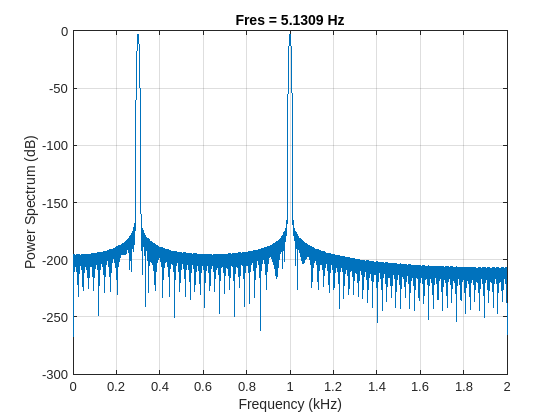

sigbad = downsample(sig, 6);
pspectrum(sigbad, fs/6)

## Task 2

The tone at 300 Hz is at the correct location, but as you saw in the slide show, the tone at 3 kHz is now aliased to 1 kHz. To reduce the aliasing, you can use an antialiasing filter before downsampling. The `resample` function will include this filter for you, but to see how it works first, you can try making your own.

`y` `=` `lowpass``(``x``,``fsNew``/``2``,``fs``)`

`z` `=` `downsample``(``y``,``n``)`

`fsNew``/``2` is Nyquist frequency after downsampling.

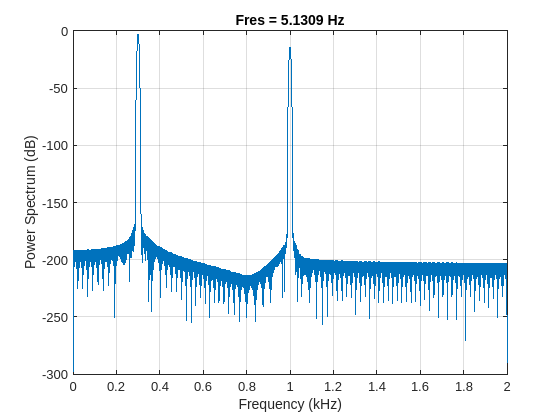

sigfilt = lowpass(sig, 2000, fs);
sigfilt = downsample(sigfilt, 6);
pspectrum(sigfilt, fs/6)

## Task 3

The power of the aliased tone decreased by about 10 dB. Now you can try using the `resample` function to decimate the signal:

`y` `=` `resample``(``x``,``p``,``q``)`

`p` and `q` are integer resample factors. The output signal `y` has `p``/``q` samples from `x`.

When you decimate, `p` is `1` because the output will have `1``/``q` samples.

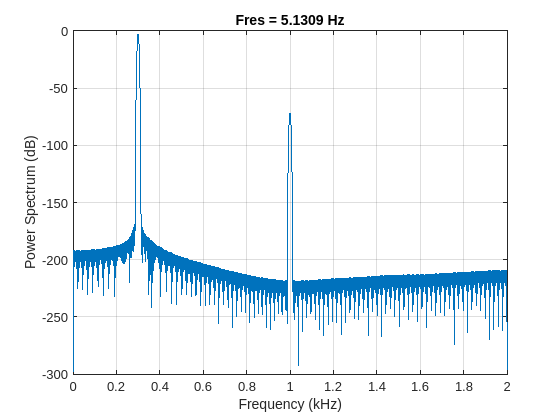

siggood = resample(sig, 1, 6);
pspectrum(siggood, fs/6)

## Further Practice

Change this to `true` to hear the tones.

playsound = true;
if playsound
    soundsc(sig, fs)
    pause(1.2)
    
    soundsc(sigbad, fs/6)
    pause(1.2)
    
    soundsc(siggood, fs/6)        
end